M=Tool.V2M(x,12,12);
cm=[[M(1:11,1:12),zeros(11,1)];zeros(1,13);[M(12,1:12),0]];
cm=roundn(cm,-1)

cm = 	1.0e+03 *

         0    0.0388         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0108    0.0357         0         0         0         0    0.0781    0.0303    0.0182    0.0315         0
         0         0         0    0.0013         0         0         0         0         0         0    0.0838         0         0
         0         0         0         0    0.0901    0.1186         0         0         0         0         0         0         0
         0    0.0007         0    0.0020         0         0         0         0    0.0031         0         0    0.0844         0
    0.0538         0         0         0         0         0    0.0013    0.1100         0         0         0         0         0
         0         0         0         0         0    0.0013         0         0         0         0         0         0         0
         0    0.0209    0.0301         0         0         0      

ids={'生活消防用水系统';
'一期循环冷却水系统';
'二期循环冷却水系统';
'综合水处理系统(处理)';
'综合水处理系统(富集)';
'化学除盐水系统（处理）';
'化学除盐水系统（富集）';
'锅炉用水系统';
'脱硫用水系统';
'灰渣系统';
'其他用水系统';
'排水';
'新鲜水';
}

ids = 13×1 cell 数组
    {'生活消防用水系统'     }
    {'一期循环冷却水系统'   }
    {'二期循环冷却水系统'   }
    {'综合水处理系统(处理)' }
    {'综合水处理系统(富集)' }
    {'化学除盐水系统（处理）'}
    {'化学除盐水系统（富集）'}
    {'锅炉用水系统'        }
    {'脱硫用水系统'        }
    {'灰渣系统'           }
    {'其他用水系统'        }
    {'排水'              }
    {'新鲜水'             }


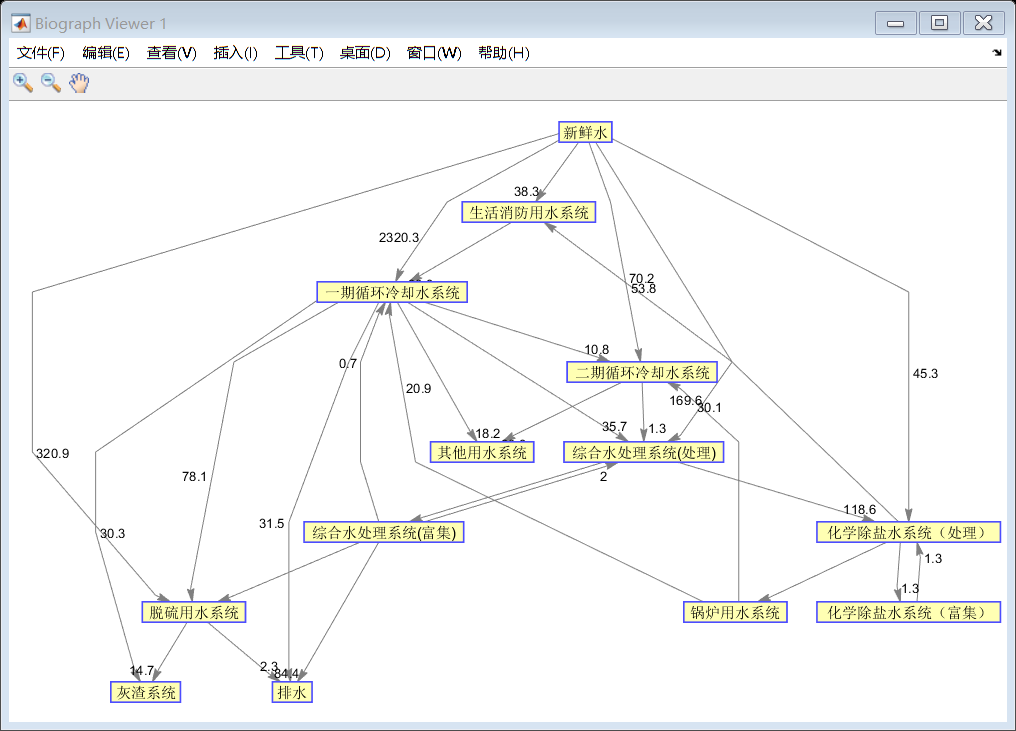

bg = biograph(cm,ids,'LayoutType','hierarchical', ...
    'EdgeType','segmented', ...
    'ShowArrows','on',...
    'NodeAutoSize','on', ...
    'ShowWeights','on');
view(bg);